computation time of reachable set: 0.45199


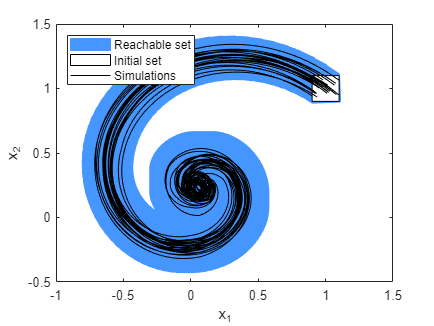

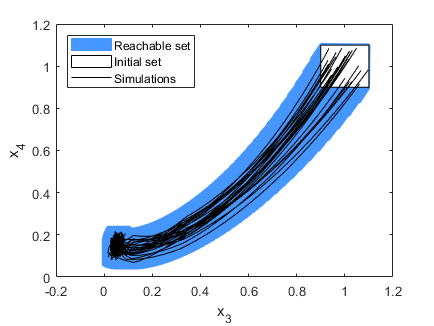

linearModel



%second cycle
i = 1;
x = 0

x = 0

for i = 1:25
    x = 0 + simRes.x{i,1}(end,:)
end

x =     0.0210    0.2109    0.0905    0.2059   -0.2656


x =     0.0168    0.3345    0.0483    0.0910   -0.2018


x =     0.0889    0.2482    0.0538    0.1527   -0.2687


x =    -0.0071    0.2106    0.0495    0.1828   -0.3276


x =     0.1425    0.2181    0.0508    0.1870   -0.2621


x =     0.0222    0.3029    0.0451    0.1749   -0.2339


x =    -0.0002    0.3359    0.0523    0.1624   -0.3040


x =     0.1029    0.1888    0.0282    0.1790   -0.1808


x =     0.0067    0.2232    0.0284    0.1567   -0.3340


x =     0.0625    0.2740    0.0573    0.1022   -0.1814


x =     0.0680    0.2807    0.0466    0.1535   -0.2392


x =     0.0016    0.2361    0.0594    0.1545   -0.3139


x =     0.1488    0.2813    0.0305    0.1430   -0.1987


x =     0.0251    0.2950    0.0583    0.1317   -0.2552


x =     0.0977    0.2270    0.0492    0.1037   -0.1925


x =     0.0309    0.2409    0.0282    0.1381   -0.2891


x =     0.0119    0.2469    0.0175    0.0940   -0.3083


x =     0.0528    0.2622    0.0491    0.1687   -0.1695


x =     0.0951    0.2000    0.0381    0.1271   -0.2450


x =     0.0101    0.1992    0.0672    0.1737   -0.3456


x =     0.0430    0.1950    0.0486    0.1306   -0.2445


x =     0.0441    0.1699    0.0639    0.1160   -0.2788


x =     0.1262    0.2158    0.0405    0.1732   -0.2172


x =     0.0486    0.2043    0.0360    0.1117   -0.1859


x =     0.0225    0.2673    0.0519    0.0952   -0.1676


x = x/25        

x =     0.0009    0.0107    0.0021    0.0038   -0.0067





% Parameters --------------------------------------------------------------

params.tFinal = 2;
params.R0 = zonotope([x',0.1*diag(ones(5,1))]);
%params.R0 = bb;
params.U = zonotope(interval([0.9; -0.25; -0.1; 0.25; -0.75], ...
                             [1.1; 0.25; 0.1; 0.75; -0.25]));


% Reachability Settings ---------------------------------------------------

options.timeStep = 0.02; 
options.taylorTerms = 4;
options.zonotopeOrder = 20; 


% System Dynamics ---------------------------------------------------------

A = [-1 -4 0 0 0; 4 -1 0 0 0; 0 0 -3 1 0; 0 0 -1 -3 0; 0 0 0 0 -2];
B = 1;

fiveDimSys = linearSys('fiveDimSys',A,B);


% Reachability Analysis ---------------------------------------------------

tic
R = reach(fiveDimSys, params, options);
tComp = toc;

disp(['computation time of reachable set: ',num2str(tComp)]);

computation time of reachable set: 0.43484


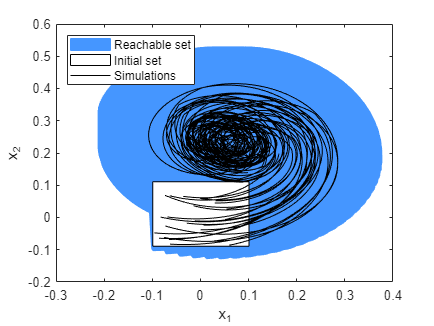

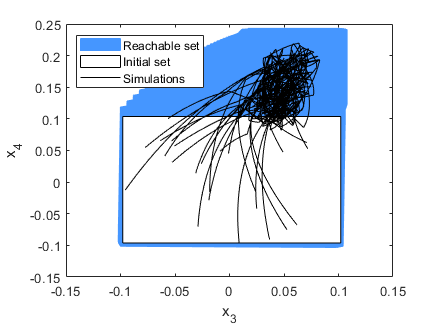



% Simulation --------------------------------------------------------------

simOpt.points = 25;
simOpt.type = 'gaussian';

simRes = simulateRandom(fiveDimSys, params, simOpt);


% Visualization -----------------------------------------------------------

% plot different projections
dims = {[1 2],[3 4]};

for k = 1:length(dims)

    figure; hold on; box on
    useCORAcolors("CORA:contDynamics")
    projDims = dims{k};

    % plot reachable sets
    plot(R,projDims, 'DisplayName', 'Reachable set');

    % plot initial set
    plot(R.R0,projDims,'DisplayName','Initial set');

    % plot simulation results
    plot(simRes,projDims, 'DisplayName', 'Simulations');

    % label plot
    xlabel(['x_{',num2str(projDims(1)),'}']);
    ylabel(['x_{',num2str(projDims(2)),'}']);
    legend('Location', 'northwest')
end


% example completed
res = true;

[f,h]=nonLinear_Gsp();
% x0=[1 15 70];
x0=[2 50 100];
[A,B,C,D]=linear_Gsp(f,h,x0)

A =          0    0.0042    0.0075
         0   -0.0500         0
         0   -0.0209   -0.0516


B =    -0.0019   -0.0500         0
         0   -2.5000         0
    0.0096         0   -0.0102


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0     0
     0     0     0
     0     0     0


input = interval([0; 0; 0;],[400; 4; 400])

input =

  [0.0000, 400.0000]
  [0.0000, 4.0000]
  [0.0000, 400.0000]



computation time of reachable set: 0.06711


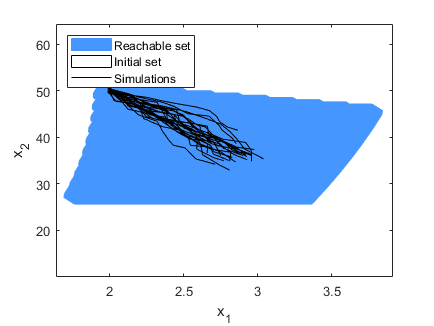

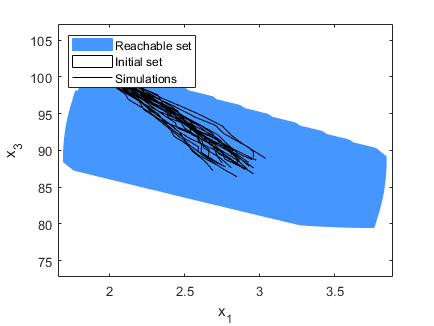

x_out =     0.1085    1.3688    3.5215


A =          0    0.0042    0.0075
         0   -1.8264         0
         0   -0.0209    0.0680


B =    -0.0019   -0.0500         0
         0   -0.0684         0
    0.0096         0   -0.9357


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0     0
     0     0     0
     0     0     0


dims = {[1 2],[1 3]};
timestep = 2;
for k =1:1
    x_out = reach_analysis_lin_dis(timestep,A,B,dims,x0,input)
    x0 = x_out;
    [A,B,C,D]=linear_Gsp(f,h,x0)
end

[f,h]=nonLinear_Gsp();
x0=[1 15 70];
%x0=[2 50 100];
[A,B,C,D]=linear_Gsp(f,h,x0)

A =          0    0.0042    0.0075
         0   -0.1667         0
         0   -0.0209   -0.0504


B =    -0.0019   -0.0500         0
         0   -0.7500         0
    0.0096         0   -0.0109


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0     0
     0     0     0
     0     0     0


input = interval([0; 0; 0;],[400; 4; 400])

input =

  [0.0000, 400.0000]
  [0.0000, 4.0000]
  [0.0000, 400.0000]



computation time of reachable set: 0.064006


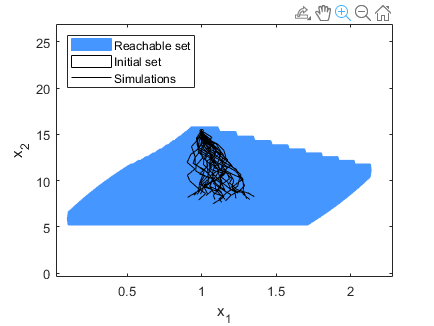

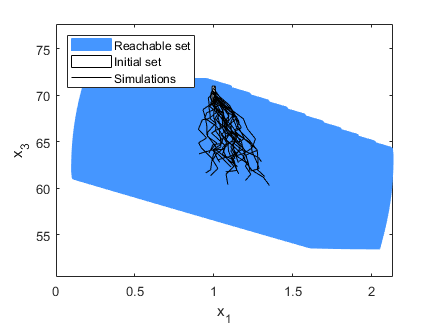

x_out =     0.0454    0.3436    2.5269


A =          0    0.0042    0.0075
         0   -7.2758         0
         0   -0.0209    0.5104


B =    -0.0019   -0.0500         0
         0   -0.0172         0
    0.0096         0  -18.2809


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0     0
     0     0     0
     0     0     0


dims = {[1 2],[1 3]};
timestep = 2;
for k =1:1
    x_out = reach_analysis_lin_dis(timestep,A,B,dims,x0,input)
    x0 = x_out;
    [A,B,C,D]=linear_Gsp(f,h,x0)
end

u1，u2 redundant

[f,h]=nonLinear_Gsp();
x0=[1 15 70];
%x0=[2 50 100];
[A,B,C,D]=linear_Gsp(f,h,x0)

A =          0    0.0042    0.0075
         0   -0.1667         0
         0   -0.0209   -0.0504


B =    -0.0019   -0.0500         0
         0   -0.7500         0
    0.0096         0   -0.0109


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0     0
     0     0     0
     0     0     0


input = interval([0; 0; 0;],[0; 0; 400])

input =

  [0.0000, 0.0000]
  [0.0000, 0.0000]
  [0.0000, 400.0000]



computation time of reachable set: 0.060798


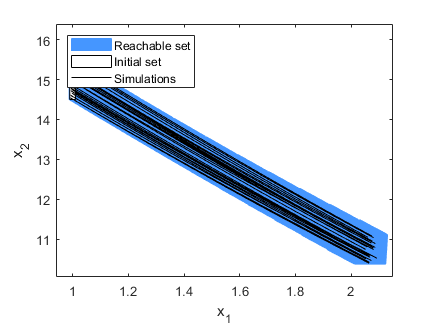

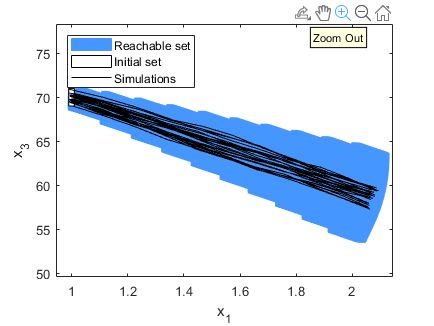

x_out =     0.0830    0.4382    2.3515


A =          0    0.0042    0.0075
         0   -5.7051         0
         0   -0.0209    0.3845


B =    -0.0019   -0.0500         0
         0   -0.0219         0
    0.0096         0  -11.0738


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0     0
     0     0     0
     0     0     0


dims = {[1 2],[1 3]};
timestep = 2;
for k =1:1
    x_out = reach_analysis_lin_dis(timestep,A,B,dims,x0,input)
    x0 = x_out;
    [A,B,C,D]=linear_Gsp(f,h,x0)
end

u2，u3 redundant

[f,h]=nonLinear_Gsp();
x0=[1 15 70];
%x0=[2 50 100];
[A,B,C,D]=linear_Gsp(f,h,x0)

A =          0    0.0042    0.0075
         0   -0.1667         0
         0   -0.0209   -0.0504


B =    -0.0019   -0.0500         0
         0   -0.7500         0
    0.0096         0   -0.0109


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0     0
     0     0     0
     0     0     0


input = interval([0; 0; 0;],[400; 0; 0])

input =

  [0.0000, 400.0000]
  [0.0000, 0.0000]
  [0.0000, 0.0000]



computation time of reachable set: 0.50013


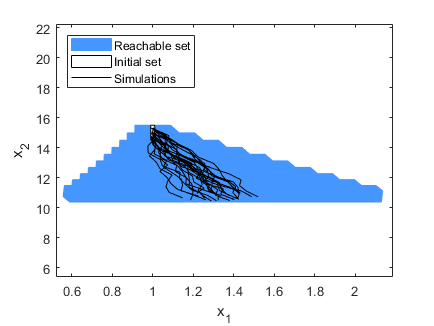

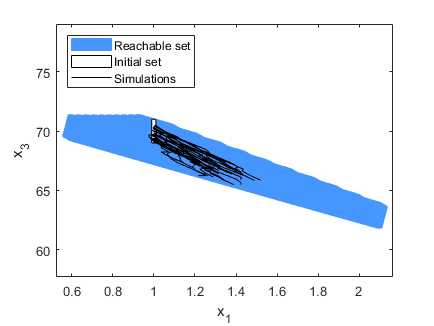

x_out =     0.0526    0.4184    2.6560


A =          0    0.0042    0.0075
         0   -5.9745         0
         0   -0.0209    0.4042


B =    -0.0019   -0.0500         0
         0   -0.0209         0
    0.0096         0  -12.1347


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0     0
     0     0     0
     0     0     0


dims = {[1 2],[1 3]};
timestep = 2;
for k =1:1
    x_out = reach_analysis_lin_dis(timestep,A,B,dims,x0,input)
    x0 = x_out;
    [A,B,C,D]=linear_Gsp(f,h,x0)
end

u1，u3 redundant

[f,h]=nonLinear_Gsp();
x0=[1 15 70];
%x0=[2 50 100];
[A,B,C,D]=linear_Gsp(f,h,x0)

A =          0    0.0042    0.0075
         0   -0.1667         0
         0   -0.0209   -0.0504


B =    -0.0019   -0.0500         0
         0   -0.7500         0
    0.0096         0   -0.0109


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0     0
     0     0     0
     0     0     0


input = interval([1; 0; 0;],[1; 4; 0])

input =

  [1.0000, 1.0000]
  [0.0000, 4.0000]
  [0.0000, 0.0000]



computation time of reachable set: 0.38275


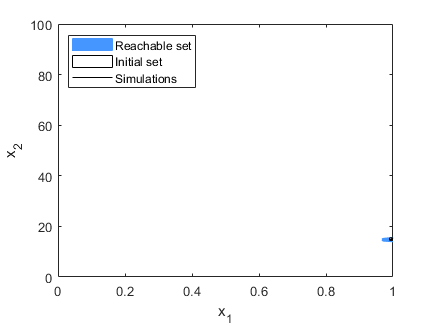

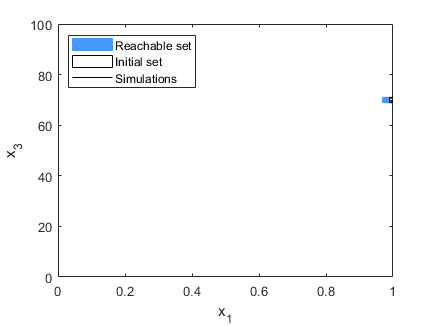

x_out =     0.0763    0.3220    2.5488


set =   reachSet with properties:

       timePoint: [1×1 struct]
    timeInterval: [1×1 struct]
          parent: 0
             loc: 0


A =          0    0.0042    0.0075
         0   -7.7643         0
         0   -0.0209    0.5496


B =    -0.0019   -0.0500         0
         0   -0.0161         0
    0.0096         0  -20.8934


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0     0
     0     0     0
     0     0     0


dims = {[1 2],[1 3]};
timestep = 2;
for k =1:1
    [x_out, set] = reach_analysis_lin_dis(timestep,A,B,dims,x0,input)
    x0 = x_out;
    R_zonotope_set = set.timePoint.set
    [A,B,C,D]=linear_Gsp(f,h,x0)
end

n = max(size(r1))

n = 11

for i = 1: n
    a1 = r1(i)
    a2 = r2(i)
    a1_zono = a1{1,1}
    a2_zono = a2{1,1}
    res(i) = a1_zono & a2_zono
end

a1 = 1×1 cell array
    {1×1 zonotope}


a2 = 1×1 cell array
    {1×1 zonotope}


a1_zono =

dimension: 3

c: 
     1
    15
    70

G: (3 generators)
    0.0100         0         0
         0    0.5000         0
         0         0    1.0000



a2_zono =

dimension: 3

c: 
     1
    15
    70

G: (3 generators)
    0.0100         0         0
         0    0.5000         0
         0         0    1.0000



Error using zonotope/interval
Too many input arguments.

Error in interval/subsasgn (line 35)
    val = interval(val,val);

S1 = interval([-1;-1],[2;2])

S1 =

  [-1.0000, 2.0000]
  [-1.0000, 2.0000]



S2 = interval([-2;-2],[1;1])

S2 =

  [-2.0000, 1.0000]
  [-2.0000, 1.0000]



res = S1 & S2

zonobundles example but not working

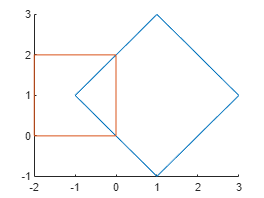

Z{1} = zonotope([1 1 1; 1 -1 1]); % create zonotope Z1;
Z{2} = zonotope([-1 1 0; 1 0 1]); % create zonotope Z2;
Zb = zonoBundle(Z); % instantiate zonotope bundle from Z1, Z2
% vol = volume(Zb) % compute and display volume of zonotope bundle

figure; hold on
plot(Z{1}); % plot Z1
plot(Z{2}); % plot Z2
hold off

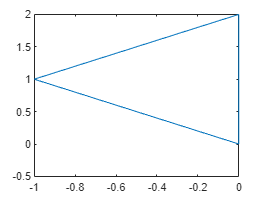

figure;
plot(Zb); % plot Zb in gray


% zonotope bundles are closed under intersections, but Minkowski addition
% is no longer exact
%% Example 1
% % convert to polytopes
% Pb = polytope(Zb)
% P1 = polytope(Z{1})
% 
% % compute exact Minkowski addition
% Pres = Pb + P1
% 
% % compute over-approximate addition
% Zres = Zb + Z{1}
% 
% % compare results
% figure; hold on
% plot(Pres); % plot Pres
% plotFilled(Zres,[1 2],[.675 .675 .675],'EdgeColor','none'); % plot Zres
% 
% %% Example 2
% % generate new zonotopes
% Z{1} = zonotope([0 0.5 1 2; 0 0.5 2 1]);
% Z{2} = zonotope([0 3 -0.7; 0 3 0.7]);
% 
% Zadd = zonotope([0 2 0; 0 0 1]); % create zonotope to be added;
% Padd = polytope(Zadd); % convert zonotope to polytope
% 
% Zbundle = zonotopeBundle(Z); % create zonotope bundle
% Pmpt = polytope(Zbundle); % convert zonotope to polytope
% 
% P_final = Pmpt + Padd; % compute exact Minkowski addition for polytopes
% Zbundle_final = Zbundle + Zadd; % compute overapprox. Minkowski addition
% 
% %plot results
% figure; hold on
% plot(Zbundle_final); % plot Zbundle_final
% plotFilled(P_final,[1 2],[.675 .675 .675],'EdgeColor','none');% plot P_final

[f,h]=nonLinear_Gsp();
x0=[1 15 70];
[A,B,C,D]=linear_Gsp(f,h,x0);
input = input_initial();
dims = {[1 2],[1 3]};
s = tic

s = uint64
5530237044074

parfor redun_situation = 1:7
    x0=[1 15 70];
    timestep = 2;
%     for k =1:1
        [x_out, set] = reach_analysis_lin_dis(timestep,A,B,dims,x0,input{redun_situation})
        x0 = x_out;
        R_zonotope_set{redun_situation} = set.timePoint.set;
%         [A,B,C,D]=linear_Gsp(f,h,x0)
%     end
end

computation time of reachable set: 0.27938
computation time of reachable set: 0.23159
computation time of reachable set: 0.2584
computation time of reachable set: 0.35189
computation time of reachable set: 0.10006
computation time of reachable set: 0.12472
computation time of reachable set: 0.09428


totalt = toc(s);
disp(totalt)

   18.8556



try to get intersection from the sets

t_intersection = tic

t_intersection = uint64
5531498654118


ZB = {};
figure();

parfor kk = 1:11 % 11 stands for eleven timepoints in the 2s simulation time
    A = {};
    for i = 1:7
        
        colum = R_zonotope_set{i};
        A{i} = colum{kk,1};
    end
    ZB{kk} = zonoBundle(A);
%     grap(kk) = figure(); hold on;
    for j = 1:length(dims)
        projDims = dims{j};
        plot(ZB{kk},projDims);
        hold on;
    end
%     projDims = [1,2,3];
%     plot(ZB{kk},projDims);
%     hold on;
end
toc(t_intersection)

Elapsed time is 1.175796 seconds.
